# Cours 23.11.22

clear; clc; close;
% Interpolation polynomiale

## Rappels

% Points d'interpolation
x = [-2 -1 1 2]

x =     -2    -1     1     2


% Valeurs interpolées
y = [10 4 6 3]

y =     10     4     6     3



% On veut construire le polyonme de degré <= 3 qui
% passe exactement par ces points
V = vander(x)

V =     -8     4    -2     1
    -1     1    -1     1
     1     1     1     1
     8     4     2     1



% Ne fonctionne pas, y doit être en matrice colonne
% a = V\y
% Donc : 
y = y'

y =     10
     4
     6
     3


a = V\y

a =    -0.9167
    0.5000
    1.9167
    4.5000


% Dans a on trouve les coefficients du polynôme (plus grand au plus petit)

% Sans construire la matrice V : on utilise polyfit
a = polyfit(x, y, 3)

a =    -0.9167    0.5000    1.9167    4.5000



% Pour évaluer le polynôme en 1 ou pusieurs points : on utilise polyval
polyval(a, -5)

ans = 122.0000

polyval(a, 5)

ans = -88.0000

polyval(a, 598)

ans = -195846640

## Dessin du polynôme et des points

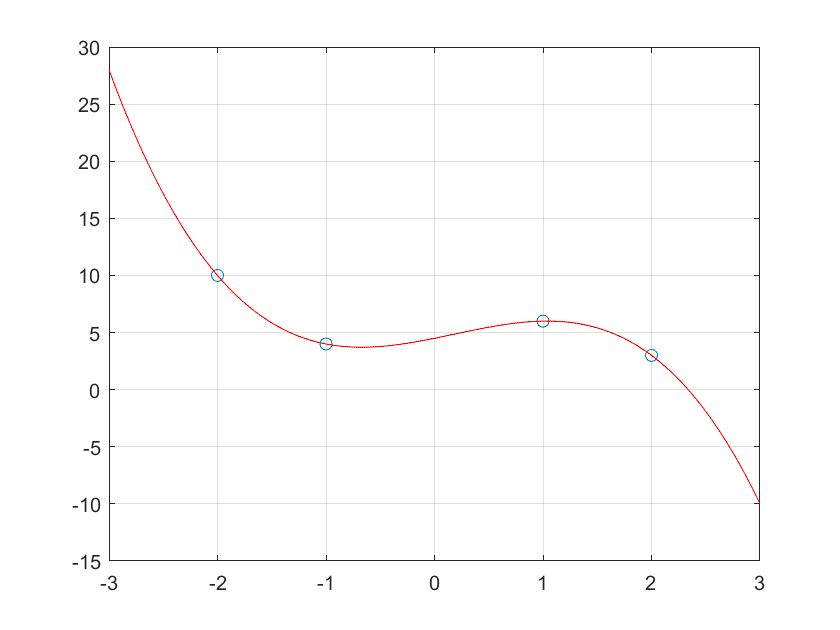

xx = linspace(-3, 3, 1e3);
p = polyval(a, xx);
plot(x, y, 'o', xx, p, 'r');
grid on;
set(gcf,'Visible','on') % Ouvre la fenêtre